columns = 14;
rows = 14;

treasureX = randi([1 columns-1])

treasureX = 5

treasureY = randi([1 rows-1]) 

treasureY = 3

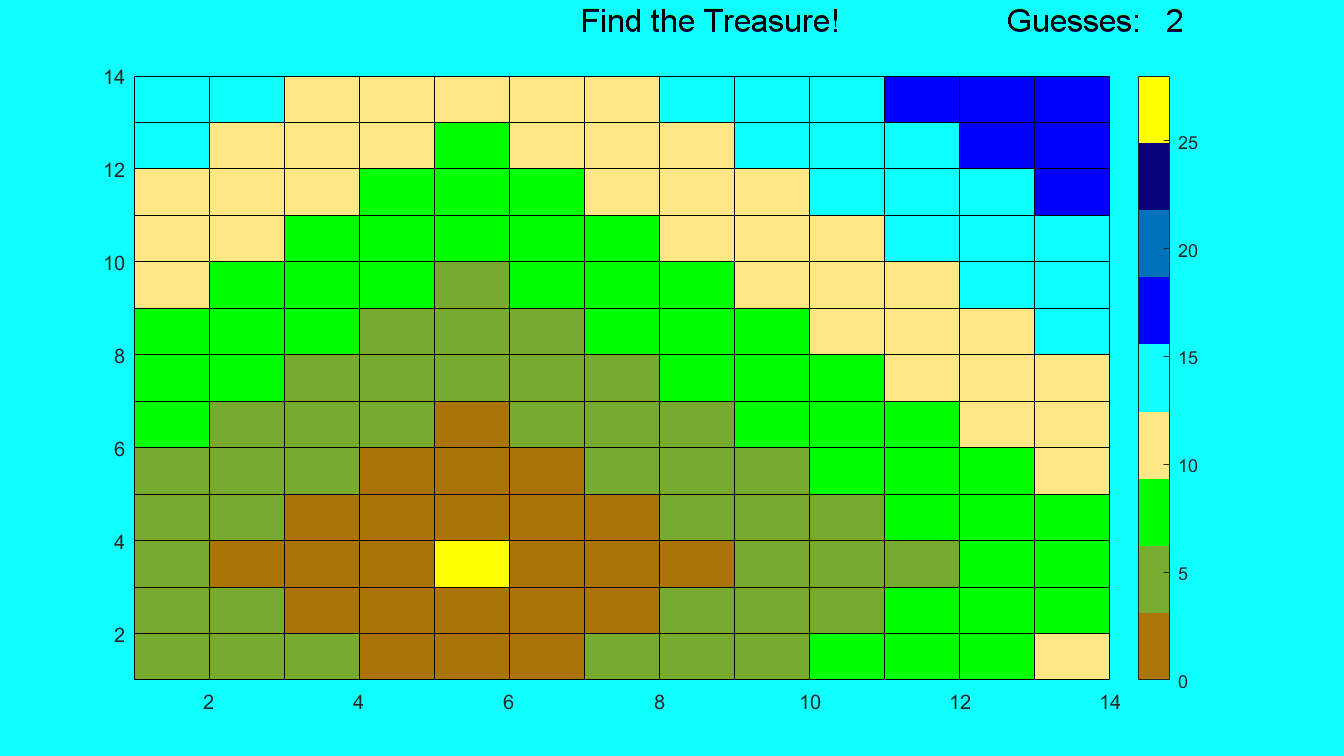

You are 4 away from the treasure.
Guess again!


You found the treasure!



map = zeros(rows, columns);

map(map == 0) = NaN;

[x2,y2] = meshgrid(1:columns,1:rows);
taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:));

finalMap = reshape(taxiMatrix,rows,columns);

%Figure Window Setup
game = figure;
backgroundColor = [0.0588 1.0000 1.0000];
set(game,'Units','Normalized','Position',[0.15 0.20 0.70 0.70],'Color',backgroundColor,'Name','Treasure Hunt','NumberTitle','Off','Resize','Off');



%Text Title
talkHandle = uicontrol(game,'Style','text');
set(talkHandle,'Units','Normalized','Position',[0.43 0.9 0.2 0.1],'BackgroundColor',backgroundColor,'String','Find the Treasure!','FontSize',16);

guesses = uicontrol(game,'Style','text');
set(guesses,'Units','Normalized','Position',[0.7 0.9 0.2 0.1],'BackgroundColor',backgroundColor,'String','Guesses:','FontSize',16);

guessNum = 0;

guessNumText = uicontrol(game,'Style','text');
set(guessNumText,'Units','Normalized','Position',[0.85 0.9 0.05 0.1],'BackgroundColor',backgroundColor,'String',guessNum,'FontSize',16);



%Add game board axes
axisHandle = axes;
set(axisHandle,'Units','Normalized','Position',[0.1 0.1 0.80 0.80],'XLim',[0 columns],'YLim',[0 rows],'XTick', 0:1:columns,'YTick', 0:1:rows,'Box','On');
grid on


finalMap(treasureY,treasureX) = 500;

pcolor(map);

cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];



colormap(cmap)
clim([0 rows*2])
colorbar
hold on
pcolor(map)


%pcolor(finalMap)
playGame(treasureX,treasureY,map,finalMap,columns,rows,guessNum,guessNumText)

function playGame(tX,tY,m,fm,c,r,gn,gnt)
    guessX = input("Choose an X value:");
    guessY = input("Choose a Y value:");

    if(guessX == tX)&&(guessY == tY)
        pcolor(fm)
        gn = gn + 1;
        set(gnt,'String',gn);
        disp("You found the treasure!")
    else
        if(guessX < c)||(guessY < r)
            m(guessY,guessX) = fm(guessY,guessX);
            pcolor(m);
            help = "You are " + string(fm(guessY,guessX)) + " away from the treasure.";
            disp(help);
        end
        disp("Guess again!");
        gn = gn + 1;
        set(gnt,'String',gn);
        playGame(tX,tY,m,fm,c,r,gn,gnt);
    end
end